a.)

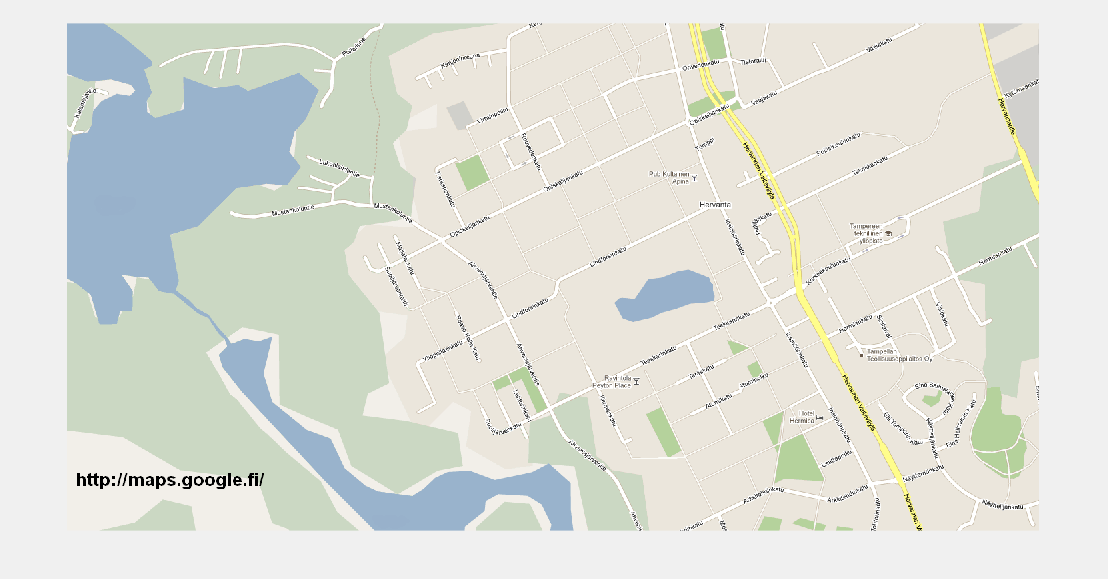

I = imread('kartta.png');
imshow(I)
[x, y] = ginput(1);

x = round(x);
y = round(y);

b.)

W = I(y(1), x(1), :);
WHSV = rgb2hsv(W);

AH = mean(WHSV(:,:,1));
AS = mean(WHSV(:,:,2));

c.)

IHSV = rgb2hsv(I);
H = IHSV(:,:,1);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

for i=1:size(IHSV, 1)
    for k=1:size(IHSV, 2)
        if ((AH - 0.1 <= IHSV(i,k,1)) & (IHSV(i,k,1) <= AH + 0.1))
            if ((AS - 0.1 <= IHSV(i,k,2)) & (IHSV(i,k,2) <= AS + 0.1))
                Bk(i, k) = 1;
            else
                Bk(i, k) = 0;
            end
        else
            Bk(i, k) = 0;
        end
    end
end

d.)

dr = 5;
reunat=imdilate(Bk,strel('disk',dr))-Bk;

e.)

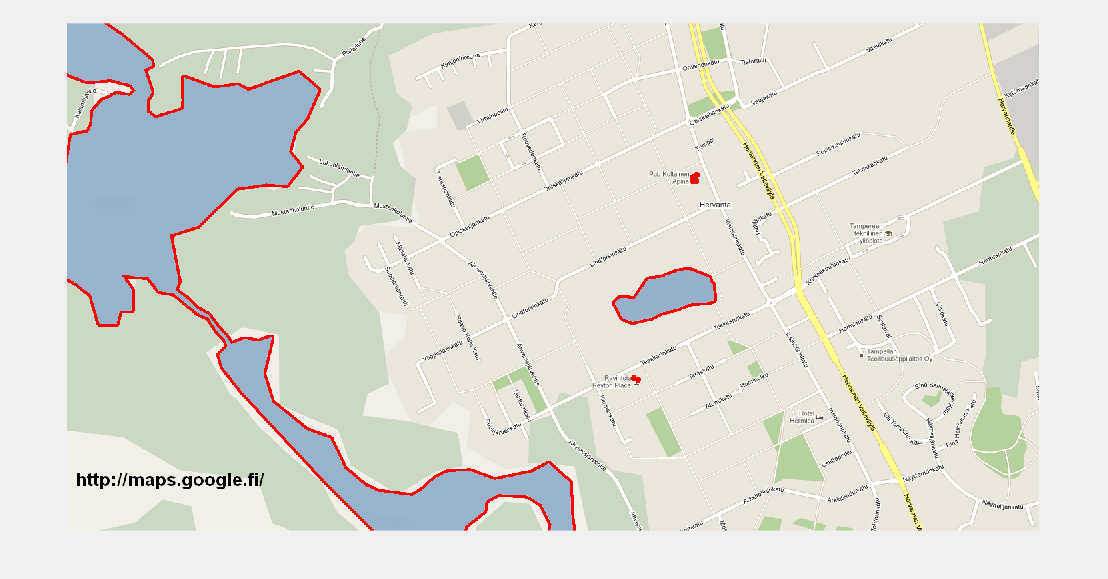

for i=1:size(reunat, 1)
    for k=1:size(reunat, 2)
        if (reunat(i, k) == 1)
            I(i, k, 1) = 255;
            I(i, k, 2) = 0;
            I(i, k, 3) = 0;
        end
    end   
end

imshow(I)

f.)

blue = 0;
other = 0;

for i=1:size(Bk, 1)
    for k=1:size(Bk, 2)
        if (Bk(i, k) == 1)
            blue = blue + 1;
        else
            other = other + 1;
        end
    end
end

percent = blue/other

percent = 0.1269

Vettä on kuvasta 12,7 %.

g.)

Oheinen segmentointi toimii huonosti, jos värikylläisyydet tai värisävyt ovat haaleita eivätkä erotu toisistaan voimakkaasti. Tällöin voidaan kuitenkin vaikkapa sinistä väriä voimistaa tai lisätä väreihin kontrastia.